# Init Global params

prefix = '1222';
bmp_path = './BMP/';
pixelSize = 0.6; % in um
levels = 256;

xCellSize = 30; % in um
yCellSize = 30; % in um
xSepSize = 30; % in um
ySepSize = 30; % in um

pattern_cells = {};

## Gen sampling pattern

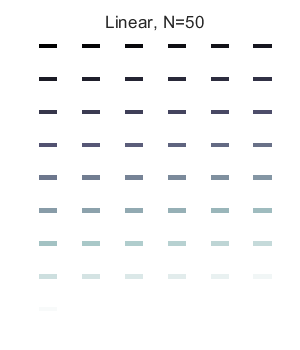

% each row contains period_list*offset_list cells
N = 50;
level_list = uint8(linspace(0,255,N)); % in um

xCellSize = 20; % in um
yCellSize = 20; % in um

figure('Position',[0 0 300 350])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,['Linear, N=',num2str(N)])
Ny = round(yCellSize/pixelSize);
for ii = 1:length(level_list)
    % horizontal arrangement
    Nx = ceil(xCellSize/pixelSize);
    I = repmat(level_list(ii),1,Nx);
    I = repmat(I,Ny,1);
    pattern_cells = [pattern_cells,I];
    nexttile
    imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
    colormap(bone)
    axis off
    caxis([0 255])
end

disp(level_list)

  列 1 至 23

     0     5    10    16    21    26    31    36    42    47    52    57    62    68    73    78    83    88    94    99   104   109   114

  列 24 至 46

   120   125   130   135   141   146   151   156   161   167   172   177   182   187   193   198   203   208   213   219   224   229   234

  列 47 至 50

   239   245   250   255



suffix = '-samp';

## Gen linear pattern

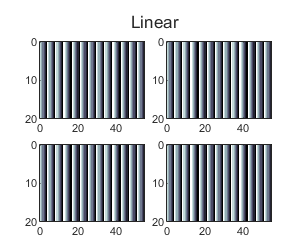

% each row contains period_list*offset_list cells
period_list = [4]; % in um
offset_list = [0,20,40,60]; % in levels

xSepSize = 0; % in um
xCellSize = 50; % in um

figure('Position',[0 0 300 250])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,'Linear')
Ny = round(yCellSize/pixelSize);
for ii = 1:length(period_list)
    Period = period_list(ii);
    % horizontal arrangement
    for nn = 1:length(offset_list)
        offset = offset_list(nn);
        % Linear pattern
        tmp = uint8(linspace(offset,levels-1,round(Period/pixelSize)));
        tmp = levels-1 - tmp;
        Nx = ceil(xCellSize/Period);
        I = repmat(tmp,1,Nx);
        I = repmat(I,Ny,1);
        pattern_cells = [pattern_cells,I];
        nexttile
        imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
        colormap(bone)
    end
end

suffix = '-lin';


## Gen Step pattern

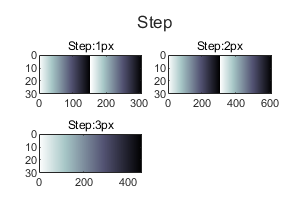

% each row contains period_list*offset_list*rep_list cells
step_list = [1,2,3]; % in pixels
rep_list = [2,2,1];
offset_list = [0]; % in levels

xSepSize = 0; % in um
xCellSize = 30; % in um
yCellSize = 30; % in um

figure('Position',[0 0 300 200])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,'Step')
Ny = round(yCellSize/pixelSize);
for ii = 1:length(step_list)
    Step = step_list(ii);
    RepTime = rep_list(ii);
    % horizontal arrangement
    for nn = 1:length(offset_list)
        offset = offset_list(nn);
        % Step pattern
        tmp = uint8(kron(offset:1:(levels-1), ones(1,Step)));
        tmp = levels-1 - tmp;
        Nx = ceil(xCellSize/length(tmp));
        tmp = repmat(repmat(tmp,1,RepTime),1,Nx);
        if nn==1
            I = tmp;
        else
            I = [I,zeros(1,round(xSepSize/pixelSize)),tmp];
        end
    end
    I = repmat(I,Ny,1);
    pattern_cells = [pattern_cells,I];
    nexttile
    imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
    colormap(bone)
    title(['Step:' num2str(step_list(ii)) 'px'])
end

suffix = '-step';


## Gen multi-level pattern

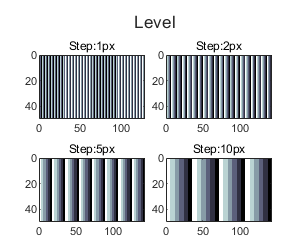

% each row contains step_list*rep_list cells
level_list = [0,50,100,150,200,255];
step_list = [1,2,5,10]; % in pixels
rep_list = [1,1,1,1]*4;

figure('Position',[0 0 300 250])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,'Level')
Ny = round(yCellSize/pixelSize);
for ii = 1:length(step_list)
    Step = step_list(ii);
    RepTime = rep_list(ii);
    % horizontal arrangement
    for nn = 1:length(offset_list)
        offset = offset_list(nn);
        % Step pattern
        tmp = uint8(kron(level_list, ones(1,Step)));
        tmp = levels-1 - tmp;
        Nx = ceil(xCellSize/length(tmp));
        tmp = repmat(repmat(tmp,1,RepTime),1,Nx);
        if nn==1
            I = tmp;
        else
            I = [I,zeros(1,round(xSepSize/pixelSize)),tmp];
        end
    end
    I = repmat(I,Ny,1);
    pattern_cells = [pattern_cells,I];
    nexttile
    imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
    colormap(bone)
    title(['Step:' num2str(step_list(ii)) 'px'])
end

suffix = '-level';

## Gen from stucture file

xCellSize = 20; % in um
yCellSize = 20; % in um
xSepSize = 100; % in um

% 读取
file_list = ls('gt_*.mat');
% 写入
figure('Position',[0 0 300 300])
t=tiledlayout('flow','TileSpacing',"compact");
title(t,'Mat file')
Ny = round(yCellSize/pixelSize);
for kk = 1:size(file_list,1)
    % load file
    load(file_list(kk,:));
    % gen cell
    I = repmat(x,Ny,1);
    Nx = ceil(xCellSize/(pixelSize*length(x)));
    I = repmat(I,1,Nx);
    I = uint8(round(I));
    pattern_cells = [pattern_cells,I];
    nexttile
    imagesc([0 pixelSize*size(I,2)],[0 pixelSize*size(I,1)],I);
    colormap(bone)
end
suffix = '-mat';

# Merge Pattern Cells along y

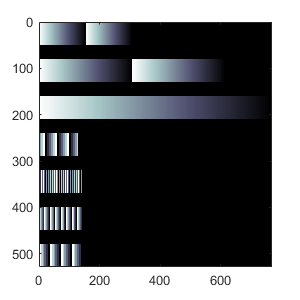

suffix = '-lin';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end
xSepSize = 30;
ySepSize = 30;
pattern_cells;
I_tot = MergeCells('y',xSepSize,ySepSize,pixelSize,pattern_cells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
figure('Position',[0 0 300 300])
imagesc([0 pixelSize*size(I_tot,2)],[0 pixelSize*size(I_tot,1)],I_tot);
colormap(bone)

disp( [bmp_path,prefix,suffix,'.bmp'])

./BMP/1222-lin.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 768.0 x 528.6 um


# Merge Pattern Cells with arrangement

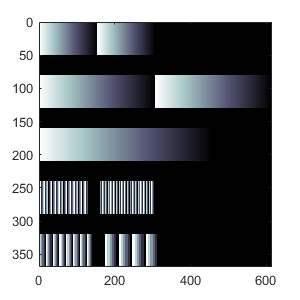

suffix = '-merged';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end
xSepSize = 30;
ySepSize = 30;
pattern_cells;
rows = [1,1,1,2,2];
I_tot = MergeCells(rows,xSepSize,ySepSize,pixelSize,pattern_cells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
figure('Position',[0 0 300 300])
imagesc([0 pixelSize*size(I_tot,2)],[0 pixelSize*size(I_tot,1)],I_tot);
colormap(bone)

disp( [bmp_path,prefix,suffix,'.bmp'])

./BMP/1222-merged.bmp


disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

Size: 614.4 x 369.0 um


# Merge BMPs 

suffix = '-merged';
try
    delete([bmp_path,prefix,suffix,'.bmp'])
end

BmpCells = LoadBmpList(bmp_path,prefix);
xSepSize = 30;
ySepSize = 30;
I_tot = MergeCells('y',xSepSize,ySepSize,pixelSize,BmpCells);

imwrite(I_tot, [bmp_path,prefix,suffix,'.bmp']);
imshow(I_tot)
disp( [bmp_path,prefix,suffix,'.bmp'])
disp(['Size: ' sprintf('%.1f',size(I_tot,2)*pixelSize),' x ',sprintf('%.1f',size(I_tot,1)*pixelSize), ' um'])

function BmpCells = LoadBmpList(bmp_path,prefix)
bmp_list = ls([bmp_path,prefix,'*.bmp']);
BmpCells = cell(1,size(bmp_list,1));
for kk = 1:size(bmp_list,1)
    % load file
    BmpCells{kk} = imread([bmp_path,bmp_list(kk,:)]);
end
end

function I_tot = MergeCells(layout,xSepSize,ySepSize,pixelSize,pattern_cells)
if isnumeric(layout)
    if length(layout)==2
        if layout(1)==1
            layout = 'x';
        elseif layout(2)==1
            layout = 'y';
        end
    end
end
% 沿x排列
if strcmp(layout,'x')
    for kk = 1:length(pattern_cells)
        % load pattern
        I = pattern_cells{kk};
        % horizontal stacking
        if kk==1
            I_tot = I;
        else
            if size(I,1)>size(I_tot,1)
                I_tot = [[I_tot;zeros(size(I,1)-size(I_tot,1),size(I_tot,2))],...
                    zeros(size(I,1),round(xSepSize/pixelSize)), I];
            else
                I_tot = [I_tot,...
                    zeros(size(I_tot,1),round(xSepSize/pixelSize)),...
                    [I;zeros(size(I_tot,1)-size(I,1),size(I,2))]];
            end
        end
    end
% 沿y排列
elseif strcmp(layout,'y')
    for kk = 1:length(pattern_cells)
        % load file
        I = pattern_cells{kk};
        % vertical stacking
        if kk==1
            I_tot = I;
        else
            if size(I,2)>size(I_tot,2)
                I_tot = [I_tot,zeros(size(I_tot,1),size(I,2)-size(I_tot,2));...
                    zeros(round(ySepSize/pixelSize),size(I,2)); I];
            else
                I_tot = [I_tot;...
                    zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                    I,zeros(size(I,1),size(I_tot,2)-size(I,2))];
            end
        end
    end
else
    % 沿Nx列 Ny行排列
    if length(layout)==2
        Nx = layout(1);
        Ny = layout(2);
        for kk = 1:length(pattern_cells)
            % load file
            I = pattern_cells{kk};
            xind = mod(kk,Nx);
            yind = ceil(kk/Nx);
            if xind==1
                I_horizon = I;
            else
                % horizontal stacking
                if size(I,1)>size(I_horizon,1)
                    I_horizon = [[I_horizon;zeros(size(I,1)-size(I_horizon,1),size(I_horizon,2))],...
                        zeros(size(I,1),round(xSepSize/pixelSize)), I];
                else
                    I_horizon = [I_horizon,...
                        zeros(size(I_horizon,1),round(xSepSize/pixelSize)),...
                        [I;zeros(size(I_horizon,1)-size(I,1),size(I,2))]];
                end
            end
            % 一行排满
            if xind==0 || kk==length(pattern_cells)
                % vertical stacking
                if yind==1
                    I_tot = I_horizon;
                else
                    if size(I_horizon,2)>size(I_tot,2)
                        I_tot = [I_tot,zeros(size(I_tot,1),size(I_horizon,2)-size(I_tot,2));...
                            zeros(round(ySepSize/pixelSize),size(I_horizon,2)); I_horizon];
                    else
                        I_tot = [I_tot;...
                            zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                            I_horizon,zeros(size(I_horizon,1),size(I_tot,2)-size(I_horizon,2))];
                    end
                end
            end
        end
    else
        % 沿列数矩阵规定的列数依次排列各行
        ind = 1;
        if_first_row = 1;
        for kk = 1:length(pattern_cells)
            % load file
            I = pattern_cells{kk};
            Nx = layout(ind);
            xind = mod(kk-sum(layout(1:ind-1)),Nx);
            if xind==1 || Nx==1
                I_horizon = I;
            else
                % horizontal stacking
                if size(I,1)>size(I_horizon,1)
                    I_horizon = [[I_horizon;zeros(size(I,1)-size(I_horizon,1),size(I_horizon,2))],...
                        zeros(size(I,1),round(xSepSize/pixelSize)), I];
                else
                    I_horizon = [I_horizon,...
                        zeros(size(I_horizon,1),round(xSepSize/pixelSize)),...
                        [I;zeros(size(I_horizon,1)-size(I,1),size(I,2))]];
                end
            end
            % 一行排满
            if xind==0 || kk==length(pattern_cells)
                ind = ind+1;
                % vertical stacking
                if if_first_row==1
                    I_tot = I_horizon;
                    if_first_row = 0;
                else
                    if size(I_horizon,2)>size(I_tot,2)
                        I_tot = [I_tot,zeros(size(I_tot,1),size(I_horizon,2)-size(I_tot,2));...
                            zeros(round(ySepSize/pixelSize),size(I_horizon,2)); I_horizon];
                    else
                        I_tot = [I_tot;...
                            zeros(round(ySepSize/pixelSize),size(I_tot,2));...
                            I_horizon,zeros(size(I_horizon,1),size(I_tot,2)-size(I_horizon,2))];
                    end
                end
            end
        end
    end
end
end